# **LI-DTI: Linear Interpretable Drug-Target Interaction **

**Prospective Evaluation**

- Output: Calculate and plot the Recall per drug for the prospective evaluation in the prospective dataset. 

## Initialization 

clear all; 

## Read the data

R = load('../prospective_evaluation/mat_drug_protein.txt');
drugNames = textread('../prospective_evaluation/drug.txt','%s');
protNames = textread('../prospective_evaluation/protein.txt','%s');

We filter out drugs and targets without associations (from the side information as well)

indexProt = sum(R,1) > 0;
indexDrug = sum(R,2) > 0;
R = R(indexDrug,indexProt);
drugNames = drugNames(indexDrug);
protNames = protNames(indexProt);
topN = [1 3 5 10 20 50 100];

chemSim = load('../data/luo_dataset/Similarity_Matrix_Drugs.txt');
% chemSim = chemSim - eye(size(chemSim));
chemSim = chemSim(indexDrug,indexDrug);
drugSim = {chemSim};
drugTresh = {0.60};

Retrive and order the new DTI for the reduced data

R2022 = load('../prospective_evaluation/drug_target_2022.mat','R');
R2022 = R2022.R;

newDrugNames = textread('../prospective_evaluation/drugs.txt','%s');
newProtNames = textread('../prospective_evaluation/targets.txt','%s');
indexNewDrugs = zeros(1,length(drugNames));
for i = 1:length(drugNames)
    if ~isempty(find(strcmp(newDrugNames,drugNames{i})))
           indexNewDrugs(i) = find(strcmp(newDrugNames,drugNames{i}));
    else
           indexNewDrugs(i) = length(drugNames)+1;
    end
end
indexNewTargets = zeros(1,length(protNames));
for i = 1:length(protNames)
    if ~isempty(find(strcmp(newProtNames,protNames{i})))
           indexNewTargets(i) = find(strcmp(newProtNames,protNames{i}));
    else
           indexNewTargets(i) = length(drugNames)+1;
    end
end

tmp = zeros(length(newDrugNames)+1,length(newProtNames)+1);
tmp(1:length(newDrugNames),1:length(newProtNames)) = R2022;
R2022 = tmp(indexNewDrugs,indexNewTargets);

indexZeros2020 = find((sum(R2022) == 0));
R2022(:,indexZeros2020) = R(:,indexZeros2020);
indexZeros2020 = find((sum(R2022,2) == 0));
R2022(indexZeros2020,:) = R(indexZeros2020,:);

newDTI = ~R & R2022;
[XCoord,YCoord] = find(newDTI == 1);
test_fold = [XCoord YCoord ones(size(XCoord))];

## LI-DTI

load('../repository/prospective_evaluation/our_method_prospective.mat');

[OurMethod_constrained_RecallRow, OurMethod_constrained_RecallCol] =average_evaluation_at_top_N(test_fold, Res,R,topN);
% OurMethod_constrained_RecallCol = mean_row_wise_evaluation(test_fold, Res,R);

## NeoDTI

load('../repository/prospective_evaluation/NeoDTI_prospective_predictions.mat');

[recallRowNeoDTI,recallColNeoDTI] = average_evaluation_at_top_N(test_fold, results,R,topN);
% recallColNeoDTI = looEvaluation(topN, XCoord, YCoord,R,results,'col');

## KGE_NFM

load('../repository/prospective_evaluation/KGE_prospective_predictions.mat');

[recallRow_KGE,recallCol_KGE ] = average_evaluation_at_top_N(test_fold, KGE_pred,R,topN);
% recallCol_KGE = looEvaluation(topN, XCoord, YCoord,R,KGE_pred,'col');

## DTINet

load('../repository/prospective_evaluation/DTINet_prospective_predictions.mat');

[recallRow_DTINet,recallCol_DTINet ] = average_evaluation_at_top_N(test_fold, DTINetResults,R,topN);
% recallCol_DTINet = looEvaluation(topN, XCoord, YCoord,R,DTINetResults,'col');

## HampDTI

load('../repository/prospective_evaluation/hampDTI_prospectivePredictions.mat');
hampDTI_predictions = best_pred;

[recallRow_hampDTI,recallCol_hampDTI] = average_evaluation_at_top_N(test_fold, hampDTI_predictions,R,topN);

Plot the average recall per drug for the prospective evaluation 

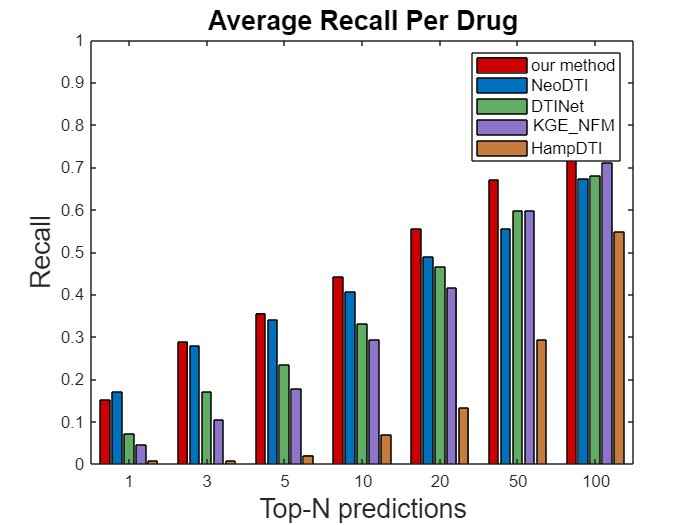

figure;
% subplot(1,2,1);
ba = bar([OurMethod_constrained_RecallRow' recallRowNeoDTI' recallRow_DTINet' recallRow_KGE' recallRow_hampDTI'],'FaceColor','flat');
ba(1).CData = [204 0 0]./255;
ba(2).CData = [0 114 189]./255;
ba(3).CData = [98,173,100]./255;
ba(4).CData = [141 117 202]./255;
ba(5).CData = [197,124,60]./255;
xticklabels(topN);
title('Average Recall Per Drug', 'FontSize', 16);
ylim([0 1]);
ylabel('Recall', 'FontSize', 16);
xlabel('Top-N predictions', 'FontSize', 16);
grid off;

legend(['our method'],['NeoDTI'],['DTINet'],['KGE\_NFM'],['HampDTI'], 'FontSize', 10);

% prospective = [topN' OurMethod_constrained_RecallRow' recallRowNeoDTI' recallRow_DTINet' recallRow_KGE' recallRow_hampDTI'];
%save("../../repository/paper_data/prospective2022_mixed.mat",'prospective');

% save('../../repository/prospective_int/DTI2022.mat','R2022');
% Ytest = test_fold;
% save('../../repository/prospective_int/Ytest.mat','Ytest');

% save('../../repository/prospective_int/drugNames.mat','drugNames');
% save('../../repository/prospective_int/protNames.mat','protNames');

% T = cell2table(drugNames)
% Write the table to a CSV file
% writetable(T,'../../repository/prospective_int/drugNames.csv');

% T = cell2table(protNames)
% % Write the table to a CSV file
% writetable(T,'../../repository/prospective_int/protNames.csv')